# Varying population size; gap length

## load and preprocess data

fds = fileDatastore('N-*.mat', 'ReadFcn', @importdata);
Filenames = fds.Files;
npop = length(Filenames);

pop = zeros(1,npop);
C = cell(1,npop);
for i = 1:npop
    load(Filenames{i});
    C{1,i} = c;
    nums = regexp(Filenames{i},'\d*','Match');
    nums = str2double(nums);
    pop(i) = nums(end);
end

[pop, order] = sort(pop);
[r,c] = size(pop);
index = bsxfun( @plus, order, (0:r-1)'*c );
C = C';
C = C(index')';

## analyze data: part 1

% get exponential fit between dimensionless time constant and dimensionless
% gap length
warning('off','all')
ntrials = 10;
A = zeros(10,npop); 
B = zeros(10,npop);

for k = 1:npop
    c = C{k};
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda2 = params(:,2);
    k2 = params(:,4);
    fr_exact = params(:,5);
    fr2 = lambda2./k2;
    fr2_round = round(fr2);  
       
    for l = 1:10
        rows = find(fr2_round == l);
        if ~isempty(rows)
            all_X = [];
            all_Y = [];
            for j = 1:length(rows)
                row = rows(j);  
                tau_vec = c{row,1}.performance(:,1);
                Gap = zeros(length(tau_vec),ntrials);
                for i = 1:ntrials
                    Gap(:,i) = c{row,i}.performance(:,2);
                end
                Gap2 = reshape(Gap,1,[]);
                Tau = repmat(tau_vec,ntrials,1); 
                X = Tau.*fr_exact(row)./1000;
                Y = Gap2.*fr_exact(row)./1000;
                % can average Y values that have the same X value (average across
                % trials)
                X_vals = unique(X);
                Y_vals = zeros(length(X_vals),1);
                for i = 1:length(X_vals)
                    Y_vals(i) = median(Y(X==X_vals(i)),'omitnan');
                end
                all_X = [all_X; X_vals];
                all_Y = [all_Y; Y_vals];
            end
            % now average together all points that have the same x value
            all_X1 = unique(all_X);
            all_Y1 = zeros(length(all_X1),1);
            for i = 1:length(all_X1)
                all_Y1(i) = median(all_Y(all_X==all_X1(i)),'omitnan');
            end
            
            mdl = fitlm(log(all_X1),log(all_Y1));
            a = mdl.Coefficients.Estimate(1);
            b = mdl.Coefficients.Estimate(2);
            A(l,k) = a;
            B(l,k) = b;
        end        
    end
end

% compute NRMSE of fits
warning('off','all')
NRMSE = nan(size(c,1),npop);

for k = 1:npop
    c = C{k};
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda2 = params(:,2);
    k2 = params(:,4);
    fr_exact = params(:,5);
    fr2 = lambda2./k2;
    fr2_round = round(fr2);  
    
    for l = 1:10
        a = A(l,k);
        b = B(l,k);
        rows = find(fr2_round == l);
        if ~isempty(rows)
            all_X = [];
            all_Y = [];
            for j = 1:length(rows)
                row = rows(j);  
                tau_vec = c{row,1}.performance(:,1);
                Gap = zeros(length(tau_vec),ntrials);
                %X_vals = tau_vec.*fr_exact(row)./1000;
                for i = 1:ntrials
                    Gap(:,i) = c{row,i}.performance(:,2);                               
                end
                Gap2 = reshape(Gap,1,[]);
                Tau = repmat(tau_vec,ntrials,1);    
                X = Tau.*fr_exact(row)./1000;
                Y = Gap2.*fr_exact(row)./1000;
                % can average Y values that have the same X value (average across
                % trials)
                X_vals = unique(X);
                Y_vals = zeros(length(X_vals),1);
                for i = 1:length(X_vals)
                    Y_vals(i) = median(Y(X==X_vals(i)),'omitnan');
                end
                
                [~, goodness] = createFit1(log(X_vals),log(Y_vals),a,b);
                NRMSE(row,k) = goodness.rmse/mean(log(Y_vals),'omitnan');
            end
        end        
    end
end

## analyze data: part 2

close all hidden;
fitresult = cell(1,npop);
for k = 1:npop
    c = C{k};
    N = pop(k);
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda2 = params(:,2);
    k2 = params(:,4);
    fr_exact = params(:,5);
    fr = round(fr_exact,-1);
    fr2 = lambda2./k2;
    fr2_round = round(fr2);  
    
    x = fr2;
    y = NRMSE(:,k);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    for j = 1:length(fit_x) 
        fit_y(j) = median(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    [fitresult{k}, ~] = createFit2(fit_x, fit_y, all_x, all_y);
end

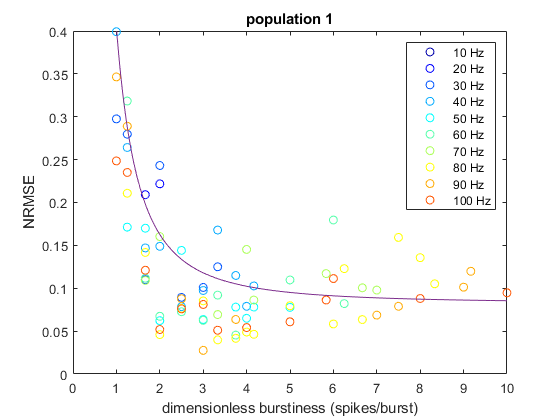

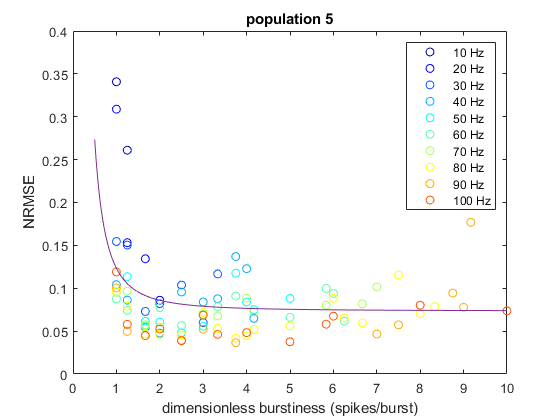

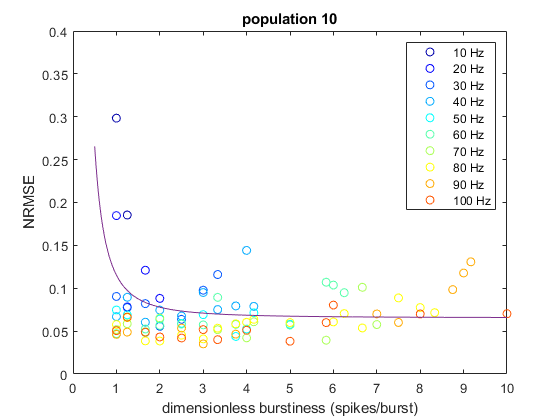

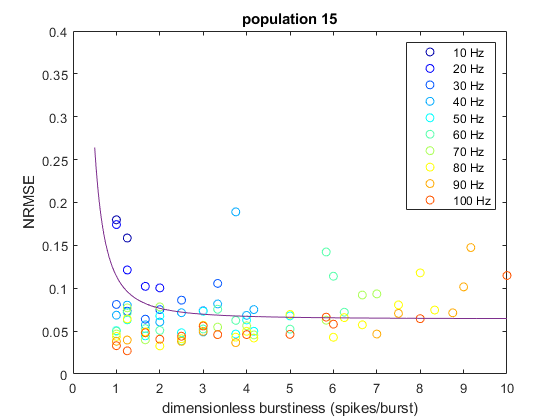

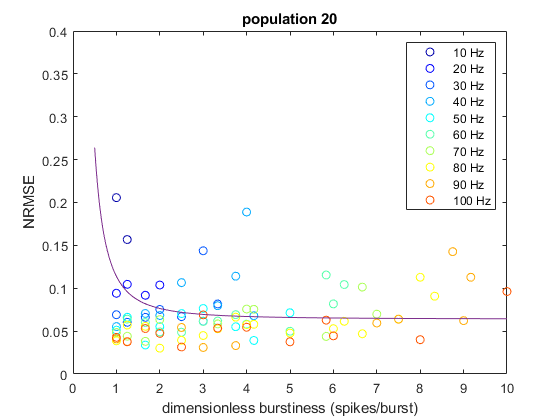

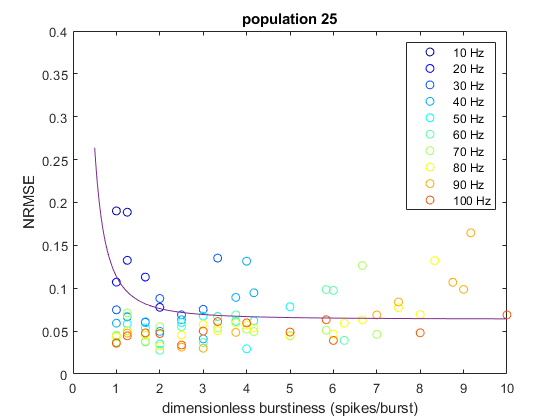

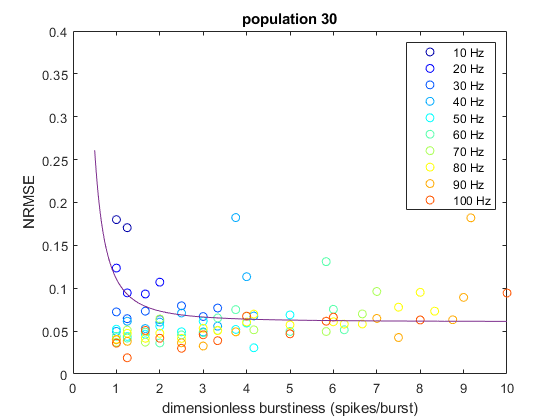

for k = 1:npop
    figure;
    c = C{k};
    N = pop(k);
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda2 = params(:,2);
    k2 = params(:,4);
    fr_exact = params(:,5);
    fr = round(fr_exact,-1);
    fr2 = lambda2./k2;
    fr2_round = round(fr2);  

    x = fr2;
    y = NRMSE(:,k);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        plot(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
        hold on
    end
    
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    for j = 1:length(fit_x) 
        fit_y(j) = median(all_y(all_x == fit_x(j)));
    end
    
    
    xx = 0.5:0.01:10;    
    yy = fitresult{k}(xx);
    plot(xx,yy)
    hold on
    hold on
    hold off
    xlim([0 10])
    ylim([0 0.4])
    ylabel('NRMSE')
    xlabel('dimensionless burstiness (spikes/burst)')  
    title(['population ', num2str(N)])
    legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')
end

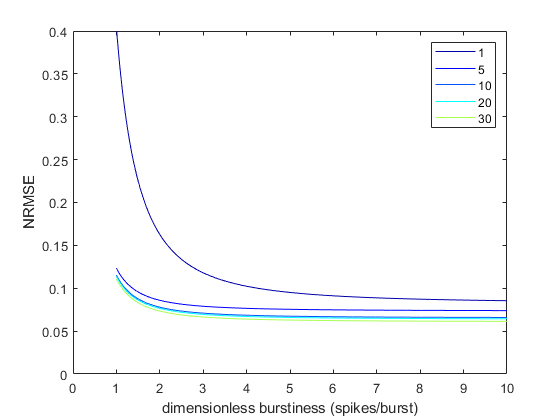

mypop = [1 2 3 5 7];
close all hidden;
for k = 1:length(mypop)
    xx = 1:0.01:10;
    yy = fitresult{mypop(k)}(xx);
    plot(xx,yy,'Color',mycolors(mypop(k),:))
    hold on
    xlim([0 10])
    ylim([0 0.4])
end
hold off
ylabel('NRMSE')
xlabel('dimensionless burstiness (spikes/burst)') 
legend('1','5','10','20','30')

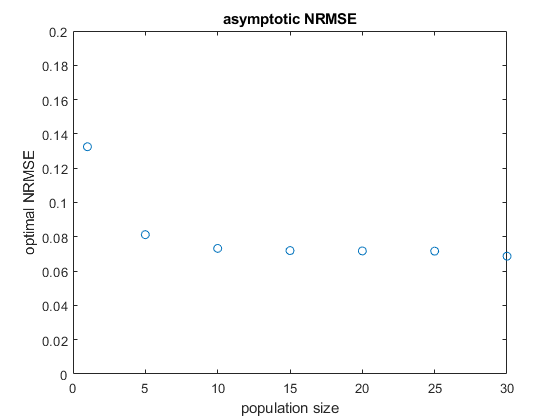

optimal_burst_prediction = zeros(npop,1);
optimal_nrmse_prediction = zeros(npop,1);
for k = 1:npop
    c = C{k};
    N = pop(k);
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda2 = params(:,2);
    k2 = params(:,4);
    fr_exact = params(:,5);
    fr = round(fr_exact,-1);
    fr2 = lambda2./k2;
    fr2_round = round(fr2);  

    x = fr2;
    y = NRMSE(:,k);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr(rows) == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
        hold on
    end
    xx = 1:0.01:10;
    yy = fitresult{k}(xx);
    [res_x, ind] = knee_pt(yy,xx);
    optimal_burst_prediction(k) = res_x;
    optimal_nrmse_prediction(k) = yy(ind);
end

close all hidden;
figure;
plot(pop, optimal_nrmse_prediction,'o')
ylim([0 0.2])
ylabel('optimal NRMSE')
xlabel('population size')
title('asymptotic NRMSE')

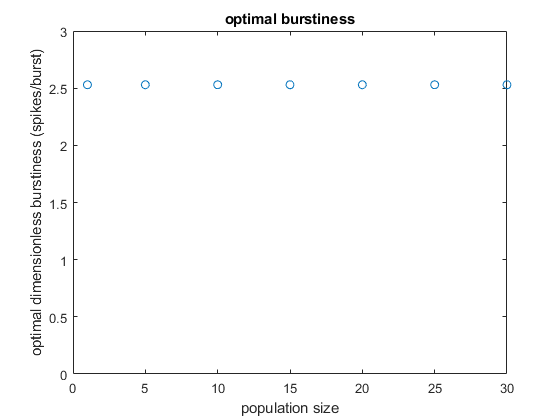


figure;
plot(pop, optimal_burst_prediction,'o')
ylim([0 3])
ylabel('optimal dimensionless burstiness (spikes/burst)')
xlabel('population size')
title('optimal burstiness')

## example plots shown in paper

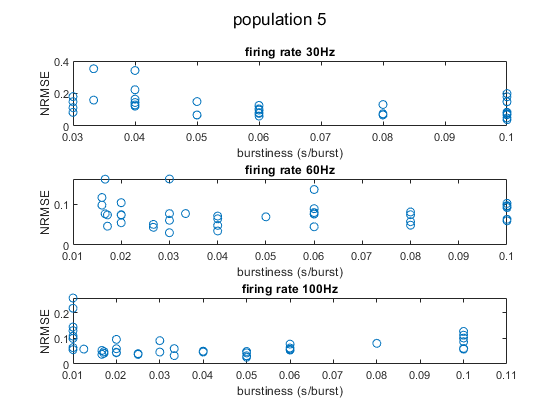

close all hidden;
vals = [30 60 100];
for j = 1:length(vals)
    c = C{2};
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda1 = params(:,1);
    k1 = params(:,3);
    burstiness = k1./lambda1;
    fr_exact = params(:,5);
    fr = round(fr_exact,-1);
    
    rows = find(fr==vals(j));
    x = burstiness(rows);
    y = NRMSE(rows,2);
    subplot(3,1,j)
    plot(x,y,'o')
    xlabel('burstiness (s/burst)')
    ylabel('NRMSE')
    title(['firing rate ', num2str(vals(j)), 'Hz'])
end
sgtitle('population 5')

close all hidden;
for k = 2
    c = C{k};
    N = pop(k);
    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda2 = params(:,2);
    k2 = params(:,4);
    fr_exact = params(:,5);
    fr = round(fr_exact,-1);
    fr2 = lambda2./k2;
    fr2_round = round(fr2);  
    
    x = fr2;
    y = NRMSE(:,k);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
    end
    
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    for j = 1:length(fit_x) 
        fit_y(j) = median(all_y(all_x == fit_x(j)));
    end
    TF = ~isnan(fit_y);
    fit_y = fit_y(TF);
    fit_x = fit_x(TF);
    [fit, gof] = createFit2(fit_x, fit_y, all_x, all_y);
end

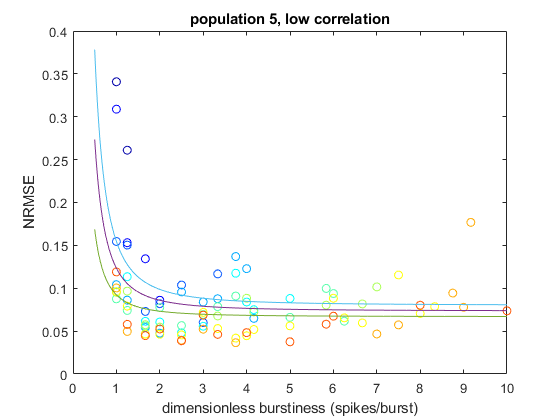

close all hidden;
for k = 2
    x = fr2;
    y = NRMSE(:,k);
    all_x = [];
    all_y = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        plot(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        all_x = [all_x; x_vals];
        all_y = [all_y; y_vals];
        hold on
    end
    
    fit_x = unique(all_x);
    fit_y = zeros(length(fit_x),1);
    for j = 1:length(fit_x) 
        fit_y(j) = median(all_y(all_x == fit_x(j)));
    end
    
    xx = 0.5:0.01:10;
    yy = fit(xx);
    alpha = 0.95;
    ci = confint(fit, alpha);
    t = tinv((1+alpha)/2, gof.dfe); 
    se = (ci(2,:)-ci(1,:)) ./ (2*t);
    a = fit.a+se(1);
    b = fit.b+se(2);
    y2 = a+(b./xx.^2);
    delta = abs(y2.'-yy);
    plot(xx,yy)
    hold on
    plot(xx,yy-delta)
    hold on
    plot(xx,yy+delta)
    hold off
    xlim([0 10])
    ylim([0 0.4])
    ylabel('NRMSE')
    xlabel('dimensionless burstiness (spikes/burst)')  
    title('population 5, low correlation')
end